%SF=7;
BW=125e3;
Fs=BW;
s=32;
SNR=-15;
errorVector=zeros(1,6);
for SF=7:12
%generate data symbol
num_samples = (2^SF)*Fs/BW;
k=s;
lora_symbol=zeros(1,num_samples);
for n=1:num_samples
    if k >= (2^SF)
        k=k-2^SF;
    end 
    k = k+1;
    lora_symbol(n)=(1/(sqrt(2^SF)))*exp(1i*2*pi*k*(k/((2^SF)*2)));
end


if false

spectrogram(lora_symbol,10,5,128,'power', 'yaxis');
[pxx,f]=spectrogram(lora_symbol,4,2,128,'power','centered', 'yaxis');

power_spectrum = sum(pxx, 2);

% Convert power to dB
power_spectrum_db = 10 * log10(abs(power_spectrum));

% % Plot the power spectrum
% figure;
% plot(f, abs(power_spectrum));
% grid on;
% title('Power Spectrum from Summed Spectrogram');
% xlabel('Frequency (Hz)');
% ylabel('Power Spectrum (dB)');
% ylim([-5, 5]);
% 
% figure
% [pxx,f] = pspectrum(lora_symbol,Fs);
% plot(f,pow2db(pxx))
% grid on
% title('1 lora symbol Freq Domain');
% xlabel('Frequency (Hz)')
% ylabel('Power Spectrum (dB)')
end


%add noise
for j = 1:round(10000/SF)%100
    lora_symbol_noisy= awgn(lora_symbol,SNR,'measured');

    
    base_down_chirp=zeros(1,num_samples);
    k=0;
    for n=1:num_samples
        if k>= (2^SF)
            k=k-2^SF;
        end
        k=k+1;
        base_down_chirp(n)=(1/(sqrt(2^SF)))*exp(-1i*2*pi*k*(k/(2^SF*2)));
    end

    dechirped=lora_symbol_noisy.*base_down_chirp;
    corrs=(abs(fft(dechirped)).^2);
    %plot(corrs)
    [~, ind]=max(corrs);
    ind2(j)=ind;
    pause(0.01)
end

%spectrogram(base_down_chirp,20,10,128,'power','centered', 'yaxis');
%spectrogram(dechirped,20,10,128,'power','centered', 'yaxis');

%histogram(ind2,2^SF)
symbol_error_rate= sum(ind2~=s+1)/j

symbol_error_rate = 0.9188

symbol_error_rate = 0.9456

symbol_error_rate = 0.8623

symbol_error_rate = 0.5730

symbol_error_rate = 0.4114

symbol_error_rate = 0.4394


%spectrogram(lora_symbol_noisy,20,10,128,'power','centered', 'yaxis');
errorVector(SF-6)=symbol_error_rate;
end


errorVector

errorVector =     0.9188    0.9456    0.8623    0.5730    0.4114    0.4394


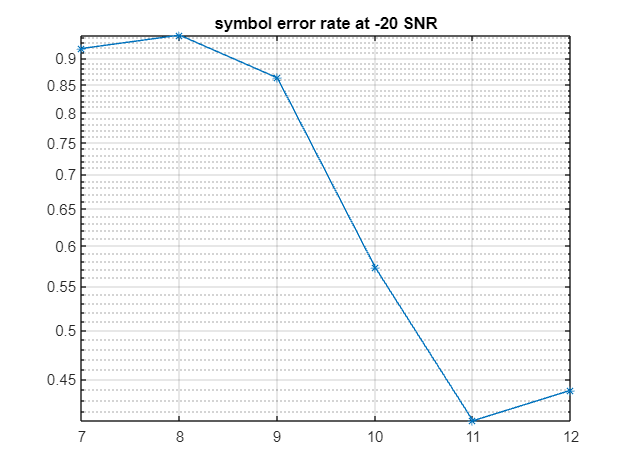

semilogy(7:12,errorVector,'-*')
title('symbol error rate at -15 SNR')
grid on
xlim([7 ,12])